# Q2(a)

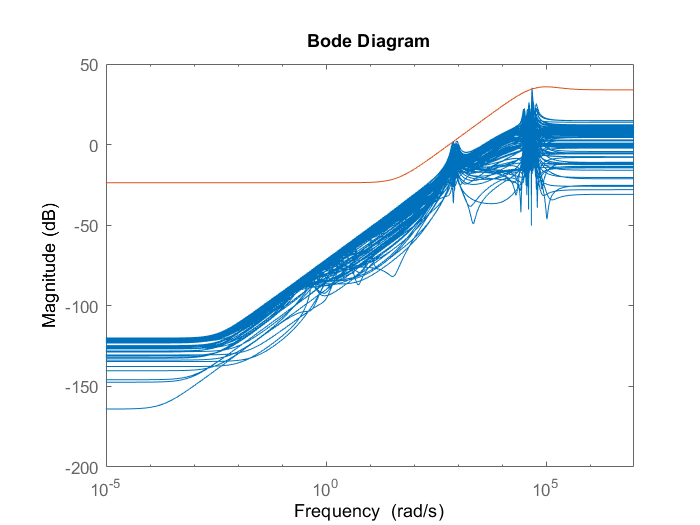

%Create VCM Plant Model
%Note:  This model is from "Design and testing of track-following
%controllers for dual-state servo systems with PZT actuated suspensions" by
%Li and Horowitz, Microsystem Technologies, 2002

%The uncertainty model is generated as follows:  
%1.)10% uncertainty in each natural frequency
%2.)20% uncertainty in each damping ratio
%3.)Multiplicative uncertainty to capture HF dynamics

%Build uncertain atoms
wv1 = ureal('wv1',135,'Percentage',10);
wv2 = ureal('wv2',5500,'Percentage',10);
wv3 = ureal('wv3',8640,'Percentage',10);
wv41 = ureal('wv41',7300,'Percentage',10);
wv42 = ureal('wv42',7650,'Percentage',10);
dv1 = ureal('dv1',0.1,'Percentage',20);
dv2 = ureal('dv2',0.03,'Percentage',20);
dv3 = ureal('dv3',0.05,'Percentage',20);
dv41 = ureal('dv41',0.03,'Percentage',20);
dv42 = ureal('dv42',0.015,'Percentage',20);
uvcm = ultidyn('uvcm',[1,1]);
Wvcm = makeweight(1e-6,5000,3);

%Construct uncertain plant
Gv = 10;  %DC Gain
Gv1 = tf((2*pi*wv1)^2,[1 2*dv1*2*pi*wv1 (2*pi*wv1)^2]);
Gv2 = tf((2*pi*wv2)^2,[1 2*dv2*2*pi*wv2 (2*pi*wv2)^2]);
Gv3 = tf((2*pi*wv3)^2,[1 2*dv3*2*pi*wv3 (2*pi*wv3)^2]);
Gv4 = wv41^2/wv42^2*tf([1 2*dv42*2*pi*wv42 (2*pi*wv42)^2],[1 2*dv41*2*pi*wv41 (2*pi*wv41)^2]);
VCM = Gv*Gv1*Gv2*Gv3*Gv4*(1+Wvcm*uvcm);

wp1 = ureal('wp1',8460,'Percentage',10);
wp21 = ureal('wp21',5500,'Percentage',10);
wp22 = ureal('wp22',5650,'Percentage',10);
wp41 = ureal('wp41',8070,'Percentage',10);
wp42 = ureal('wp42',8250,'Percentage',10);
wp51 = ureal('wp51',10650,'Percentage',10); 
wp52 = ureal('wp52',10530,'Percentage',10); 
dp1 = ureal('dp1',0.01,'Percentage',20);
dp21 = ureal('dp21',0.03,'Percentage',20);
dp22 = ureal('dp22',0.03,'Percentage',20);
dp41 = ureal('dp41',0.015,'Percentage',20);
dp42 = ureal('dp42',0.02,'Percentage',20);
dp51 = ureal('dp51',0.01,'Percentage',20);
dp52 = ureal('dp52',0.015','Percentage',20);
upzt = ultidyn('upzt',[1,1]);
Wpzt = makeweight(1e-6,8000,3);

Gp = 0.1;  %DC gain
Gp1 = tf((2*pi*wp1)^2,[1 2*dp1*2*pi*wp1 (2*pi*wp1)^2]);
Gp2 = wp21^2/wp22^2*tf([1 2*dp22*2*pi*wp22 (2*pi*wp22)^2],[1 2*dp21*2*pi*wp21 (2*pi*wp21)^2]);
Gp3 = Gv4;  %This mode is coupled between VCM and PZT
Gp4 = wp41^2/wp42^2*tf([1 2*dp42*2*pi*wp42 (2*pi*wp42)^2],[1 2*dp41*2*pi*wp41 (2*pi*wp41)^2]);
Gp5 = wp51^2/wp52^2*tf([1 2*dp52*2*pi*wp52 (2*pi*wp52)^2],[1 2*dp51*2*pi*wp51 (2*pi*wp51)^2]);
PZT = Gp*Gp1*Gp2*Gp3*Gp4*Gp5*(1+Wpzt*upzt);

VCM_uncertain = usample(VCM,100);
[P,V_info] = ucover(VCM_uncertain,VCM.NominalValue,2);
bodemag((VCM_uncertain - VCM.NominalValue)/VCM.NominalValue,V_info.W1)

V_info.W1

ans =
 
  A = 
               x1          x2
   x1  -1.766e+05  -6.841e+04
   x2   1.028e+05        5182
 
  B = 
          u1
   x1   6946
   x2  -3473
 
  C = 
           x1      x2
   y1  -674.3   -1677
 
  D = 
          u1
   y1  49.92
 
Continuous-time state-space model.



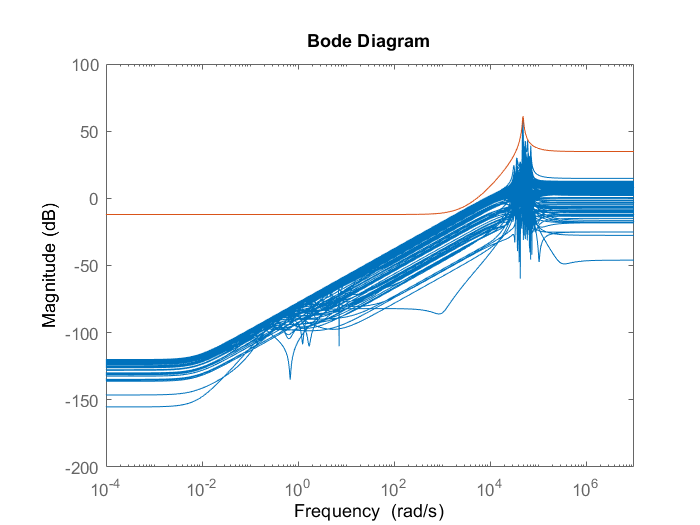


PZT_uncertain = usample(PZT,100);
[P,P_info] = ucover(PZT_uncertain,PZT.NominalValue,2);
bodemag((PZT_uncertain - PZT.NominalValue)/PZT.NominalValue,P_info.W1)

P_info.W1

ans =
 
  A = 
               x1          x2
   x1   1.564e+05  -1.637e+05
   x2   1.661e+05  -1.587e+05
 
  B = 
           u1
   x1   591.2
   x2  -591.2
 
  C = 
           x1      x2
   y1  -111.2  -574.3
 
  D = 
          u1
   y1  55.23
 
Continuous-time state-space model.



# Q2(b)

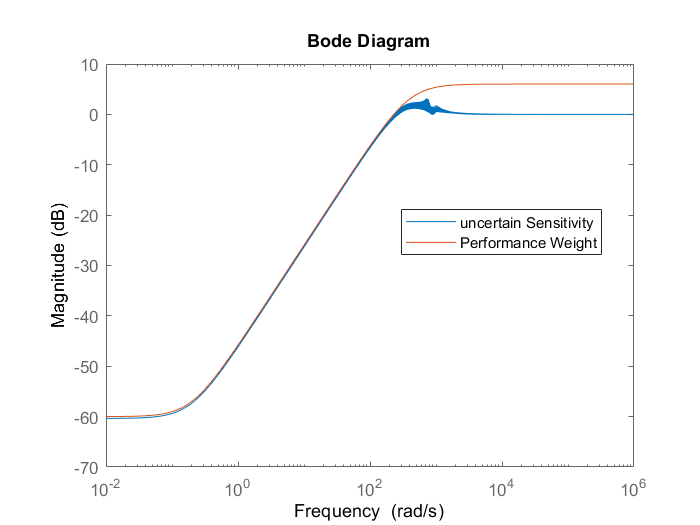

wh = 1000;  %Just guessing at this...we'll see if it fails
wl = 0;
w_try = wh;  %Just for simplicity
w_new = 1/2*(wh+wl);
Wt = V_info.W1;
while(abs(w_new-w_try)>.001)  %Stopping criterion
    w_try = w_new;
    Wp = makeweight(1000,w_try,1/2);
    [K,CL,GAM] = mixsyn(VCM.NominalValue,Wp,[],Wt);
    if GAM<1
        wl = w_try;  %We're not agressive enough
    else
        wh = w_try;  %We're too agressive
    end
    w_new = 1/2*(wh+wl);
end
S = 1/(1+VCM*K);
SS = usample(S,100);
bodemag(SS,1/Wp)
legend('uncertain Sensitivity','Performance Weight','Location','best')


norm([Wp*S;Wt*(1-S)],'inf')

ans = 1.0000

# Q2(c)

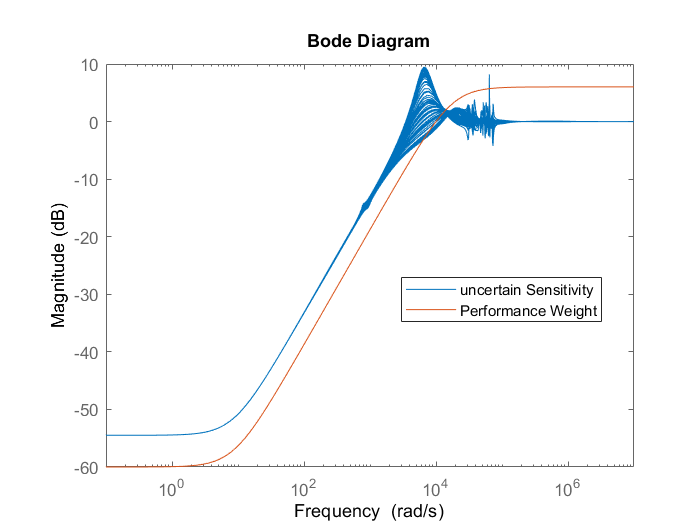

W_vcm = V_info.W1;
W_pzt = P_info.W1;
wh = 10000;  
wl = 0;
w_try = wh;  
w_new = 1/2*(wh+wl);
G = [VCM PZT];
i = 1;
Gam = [];
while(abs(w_new-w_try)>.001)  
    w_try = w_new;
    Wp = makeweight(1000,w_try,1/2);
    P = [0 0 0 W_vcm*VCM.NominalValue 0;
        0 0 0 0 W_pzt*PZT.NominalValue;
        -Wp -Wp Wp -Wp*VCM.NominalValue -Wp*PZT.NominalValue;
        -1 -1 1 -VCM.NominalValue -PZT.NominalValue];
    [K,CL,GAM] = hinfsyn(P,1,2);
    Gam(i) = GAM;
    i = i + 1;
    if GAM<3.5
        wl = w_try;  
    else
        wh = w_try;  
    end
    w_new = 1/2*(wh+wl);
end
S = 1 - feedback(G*K,1);
S = usample(S,100);
bodemag(S,1/Wp)
legend('uncertain Sensitivity','Performance Weight','Location','best')

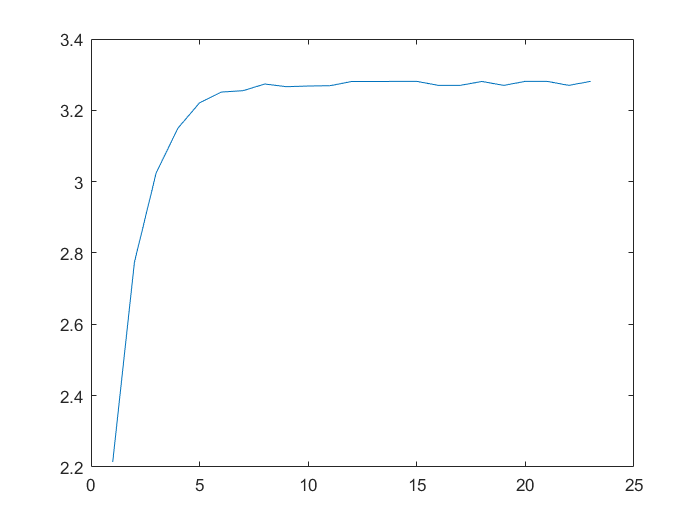

figure
plot(1:1:i-1,Gam)

From the plot, we can clearly observe that the system does not meet the criteria for robust performance. The Perfrmance weight stays below the uncertain plant sensitivity for most of the region.

% PP = [Wp -Wp*VCM -Wp*PZT;1 -VCM -PZT];
% N = lft(PP,K);
% [PERFMARG,WCU] = robustperf(N);
% mu_p = 1/PERFMARG.LowerBound